# Two particles on cone with a string

Two heavy point particles $P_1$ and $$P_2$$ of mass $$m$$ each are connected by an inextensible, massless string of total length $$\ell$$. Particle $P_1$ is constrained to move without friction over the surface of a cone of semiangle $$\alpha$$ (the particle cannot leave the surface of the cone). The string passes through an aperture at the cone vertex $$O$$, and it can slide through it without friction. Particle $$P_2$$ hangs along the cone axis, and is constrained to move along it. We define an inertial reference frame $$OXYZ$$ as shown in the figure. We call $$\xi$$ the length of the fraction of string between $O$ and $P_1$, and $\theta$ the angle  formed between the $X$ axis and the projection onto the $XY$ plane of the $OP_1$ vector.In the following, assume that the string is always tense and that the particles do not reach point $$O$$ during motion.

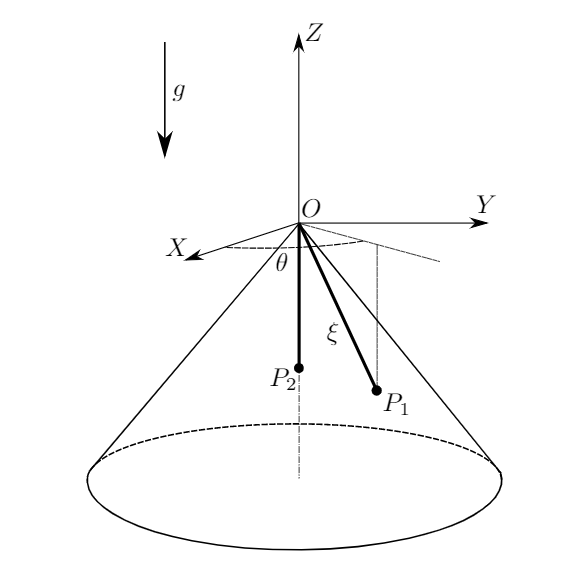

## Kinematics

import anakin.*

syms t xi(t) theta(t) ell alpha m g T(t) N(t); % declare symbolic variables 

B0 = basis;
B1 = B0.rotatez(theta);
B2 = B1.rotatey(pi/2-alpha);

O0 = point; 
S0 = frame(O0,B0) % inertial reference frame

S0 = Frame with origin with canonical position:
     0
     0
     0

And basis with canonical rotation matrix:
     1     0     0
     0     1     0
     0     0     1


S1 = frame(O0,B1)

S1 = Frame with origin with canonical position:
     0
     0
     0

And basis with canonical rotation matrix:
[ cos(theta(t)), -sin(theta(t)), 0]
[ sin(theta(t)),  cos(theta(t)), 0]
[             0,              0, 1]
 

S2 = frame(O0,B2)

S2 = Frame with origin with canonical position:
     0
     0
     0

And basis with canonical rotation matrix:
[ cos(theta(t))*sin(alpha), -sin(theta(t)), cos(theta(t))*cos(alpha)]
[ sin(theta(t))*sin(alpha),  cos(theta(t)), sin(theta(t))*cos(alpha)]
[              -cos(alpha),              0,               sin(alpha)]
 



P1 = particle(tensor(xi)*B2.e(1));
P1.pos

ans = Vector with canonical components:
 cos(theta(t))*sin(alpha)*xi(t)
 sin(theta(t))*sin(alpha)*xi(t)
              -cos(alpha)*xi(t)
 

P1.vel

ans = Vector with canonical components:
 cos(theta(t))*sin(alpha)*diff(xi(t), t) - sin(theta(t))*sin(alpha)*xi(t)*diff(theta(t), t)
 sin(theta(t))*sin(alpha)*diff(xi(t), t) + cos(theta(t))*sin(alpha)*xi(t)*diff(theta(t), t)
                                                                 -cos(alpha)*diff(xi(t), t)
 

P1.accel

ans = Vector with canonical components:
 cos(theta(t))*sin(alpha)*diff(xi(t), t, t) - 2*sin(theta(t))*sin(alpha)*diff(theta(t), t)*diff(xi(t), t) - cos(theta(t))*sin(alpha)*xi(t)*diff(theta(t), t)^2 - sin(theta(t))*sin(alpha)*xi(t)*diff(theta(t), t, t)
 sin(theta(t))*sin(alpha)*diff(xi(t), t, t) + 2*cos(theta(t))*sin(alpha)*diff(theta(t), t)*diff(xi(t), t) - sin(theta(t))*sin(alpha)*xi(t)*diff(theta(t), t)^2 + cos(theta(t))*sin(alpha)*xi(t)*diff(theta(t), t, t)
                                                                                                                                                                                       -cos(alpha)*diff(xi(t), t, t)
 


P2 = particle(tensor(xi-ell)*B0.e(3));
P2.pos

ans = Vector with canonical components:
           0
           0
 xi(t) - ell
 

P2.vel

ans = Vector with canonical components:
              0
              0
 diff(xi(t), t)
 

P2.accel

ans = Vector with canonical components:
                 0
                 0
 diff(xi(t), t, t)
 

## Interactive plot

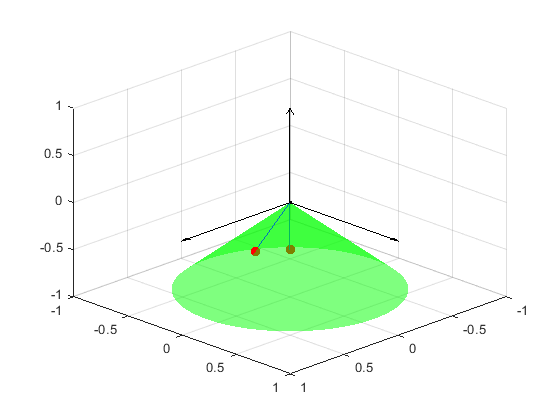

% Initial plot
m_ = 1;
g_ = 1;
alpha_ = 40*pi/180;
ell_ = 1;
xi_ = 0.5;
theta_ = 0;

f1 = figure(1);
a = axes;

tt = linspace(0,2*pi,100);
xx = linspace(0,1.2,100);
[xx,tt] = meshgrid(xx,tt);
XX = xx.*sin(alpha_).*cos(tt);
YY = xx.*sin(alpha_).*sin(tt);
ZZ = -xx.*cos(alpha_);
surf(XX,YY,ZZ,'LineStyle','none','FaceAlpha',0.5,'FaceColor','g')
view([135 30])

S0.plot; 

P1_ = P1.subs({xi,theta,alpha,ell},{xi_,theta_,alpha_,ell_});
P2_ = P2.subs({xi,theta,alpha,ell},{xi_,theta_,alpha_,ell_});
 
h1 = P1_.plot('Color','r','Marker','.','Markersize',24);
h2 = P2_.plot('Color','r','Marker','.','Markersize',24);
pos1 = P1_.pos.components;
pos2 = P2_.pos.components;
h3 = line([pos1(1),0,pos2(1)],[pos1(2),0,pos2(2)],[pos1(3),0,pos2(3)]);

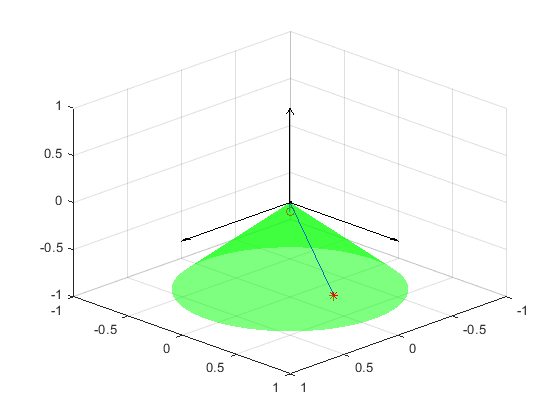

% Interactive plot
xi_ =0.9;
theta_ =1.3;

delete(h1);
delete(h2);
delete(h3);

P1_ = P1.subs({xi,theta,alpha,ell},{xi_,theta_,alpha_,ell_});
P2_ = P2.subs({xi,theta,alpha,ell},{xi_,theta_,alpha_,ell_});
 
h1 = P1_.plot('Color','r','Marker','*');
h2 = P2_.plot('Color','r','Marker','o');
pos1 = P1_.pos.components;
pos2 = P2_.pos.components;
h3 = line([pos1(1),0,pos2(1)],[pos1(2),0,pos2(2)],[pos1(3),0,pos2(3)]);

## Forces

% On P1
W1 = tensor(-m*g*[0,0,1])

W1 = Vector with canonical components:
    0
    0
 -g*m
 

T1 = tensor(tensor(T)*(-B2.e(1)))

T1 = Vector with canonical components:
 -cos(theta(t))*T(t)*sin(alpha)
 -sin(theta(t))*T(t)*sin(alpha)
                cos(alpha)*T(t)
 

N1 = tensor(tensor(N)*(B2.e(3)))

N1 = Vector with canonical components:
 cos(theta(t))*N(t)*cos(alpha)
 sin(theta(t))*N(t)*cos(alpha)
               N(t)*sin(alpha)
 


P1.forces = {W1, T1, N1};

% On P2
W2 = tensor(-m*g*[0,0,1])

W2 = Vector with canonical components:
    0
    0
 -g*m
 

T2 = tensor(T*[0,0,1]) 

T2 = Vector with canonical components:
    0
    0
 T(t)
 


P2.forces = {W2, T2};

## Equations of motion

eq1 = (P1.mass * P1.accel - W1 - T1 - N1) * B2.e(1)

eq1 = Scalar with value:
T(t) - xi(t)*diff(theta(t), t)^2 + diff(xi(t), t, t) + cos(alpha)^2*xi(t)*diff(theta(t), t)^2 - g*m*cos(alpha)
 

eq2 = (P1.mass * P1.accel - W1 - T1 - N1) * B2.e(2)

eq2 = Scalar with value:
sin(alpha)*(xi(t)*diff(theta(t), t, t) + 2*diff(theta(t), t)*diff(xi(t), t))
 

eq3 = (P1.mass * P1.accel - W1 - T1 - N1) * B2.e(3)

eq3 = Scalar with value:
g*m*sin(alpha) - N(t) - (sin(2*alpha)*xi(t)*diff(theta(t), t)^2)/2
 

eq4 = (P2.mass * P2.accel - W2 - T2) * B0.e(3)

eq4 = Scalar with value:
g*m - T(t) + diff(xi(t), t, t)
 


% To export to latex (not great):
% latex(eq1.components)

## Integration of equations of motion

eqs1 = P1.equations(B2);
eqs2 = P2.equations(B0);
eqs = [eqs1;eqs2(3)]

$$eqs = \begin{array}{l} \left(\begin{array}{c} \sigma_{2}-{\sin\left(\alpha \right)}^{2}\,\xi \left(t\right)\,\sigma_{1}=g\,m\,\cos\left(\alpha \right)-T\left(t\right)\\ \sin\left(\alpha \right)\,\left(\xi \left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\frac{\partial }{\partial t}\xi \left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,2\right)=0\\ -\frac{\sin\left(2\,\alpha \right)\,\xi \left(t\right)\,\sigma_{1}}{2}=N\left(t\right)-g\,m\,\sin\left(\alpha \right)\\ \sigma_{2}=T\left(t\right)-g\,m \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\xi \left(t\right) \end{array}$$

vars = [xi,theta,T,N]

$$vars(t) = \left(\begin{array}{cccc} \xi \left(t\right) & \theta \left(t\right) & T\left(t\right) & N\left(t\right) \end{array}\right)$$


[eqs, vars] = reduceDifferentialOrder(eqs, vars)

$$eqs = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{Dxit}\left(t\right)-\xi \left(t\right)\,{{\mathrm{Dtheta}}_{t}\left(t\right)}^{2}\,{\sin\left(\alpha \right)}^{2}+T\left(t\right)-g\,m\,\cos\left(\alpha \right)\\ \sin\left(\alpha \right)\,\left(\xi \left(t\right)\,\frac{\partial }{\partial t}{\mathrm{Dtheta}}_{t}\left(t\right)+2\,{\mathrm{Dtheta}}_{t}\left(t\right)\,\mathrm{Dxit}\left(t\right)\right)\\ -\frac{\sin\left(2\,\alpha \right)\,\xi \left(t\right)\,{{\mathrm{Dtheta}}_{t}\left(t\right)}^{2}}{2}-N\left(t\right)+g\,m\,\sin\left(\alpha \right)\\ \frac{\partial }{\partial t}\mathrm{Dxit}\left(t\right)-T\left(t\right)+g\,m\\ \mathrm{Dxit}\left(t\right)-\frac{\partial }{\partial t}\xi \left(t\right)\\ {\mathrm{Dtheta}}_{t}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

$$vars = \left(\begin{array}{c} \xi \left(t\right)\\ \theta \left(t\right)\\ T\left(t\right)\\ N\left(t\right)\\ \mathrm{Dxit}\left(t\right)\\ {\mathrm{Dtheta}}_{t}\left(t\right) \end{array}\right)$$


f = daeFunction(eqs,vars,m,g,alpha);
F = @(t, Y, YP) f(t, Y, YP, m_, g_, alpha_);

Y0est = [0.5,0,0,0,-0.2,1];
YP0est = [0,0,0,0,0,0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol' , 10.0^(-7));
[Y0, YP0] = decic(F, 0, Y0est, [], YP0est, [], opt)

Y0 =     0.5000
         0
    0.9863
    0.3966
   -0.2000
    1.0000


YP0 =    -0.2000
    1.0000
         0
         0
   -0.0137
    0.8000



[t_,y_] = ode15i(F, [0:0.05:10], Y0, YP0, opt);
f2 = figure(2)

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


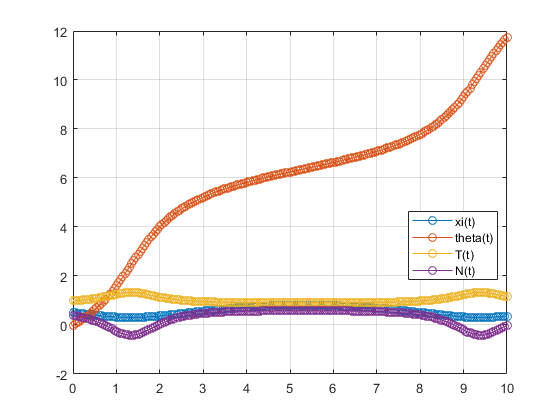

plot(t_,y_(:,1:4),'-o')

for k = 1:4
  S{k} = char(vars(k));
end

legend(S, 'Location', 'Best')
grid on

## Time movie

xi_ = y_(:,1);
theta_ = y_(:,2);
 
figure(f1);

FF(length(t_)) = struct('cdata',[],'colormap',[]);
for i = 1:length(t_)
    delete(h1);
    delete(h2);
    delete(h3);

    P1_ = P1.subs({xi,theta,alpha,ell},{xi_(i),theta_(i),alpha_,ell_});
    P2_ = P2.subs({xi,theta,alpha,ell},{xi_(i),theta_(i),alpha_,ell_});

    h1 = P1_.plot('Color','r','Marker','.','Markersize',24);
    h2 = P2_.plot('Color','r','Marker','.','Markersize',24);
    pos1 = P1_.pos.components;
    pos2 = P2_.pos.components;
    h3 = line([pos1(1),0,pos2(1)],[pos1(2),0,pos2(2)],[pos1(3),0,pos2(3)]);
    
    drawnow;
    FF(i).colormap = [];
    FF(i).cdata = print('-RGBImage','-r600');
end

f3 = figure(3);
movie(f3,FF,2)

v = VideoWriter('mymovie','MPEG-4');
v.open;
writeVideo(v,FF);
v.close;
